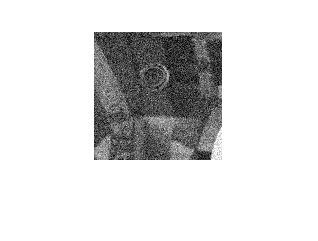

left = imread("input\pair1-L.png");
%imshow(left);
right = imread("input\pair1-R.png");
%imshow(right);
left = rgb2gray(left);
right = rgb2gray(right);
rowcol = 128;
left = left(1:rowcol, 1:rowcol);
right = right(1:rowcol, 1:rowcol);
left = imnoise(left,'gaussian');
imshow(left);

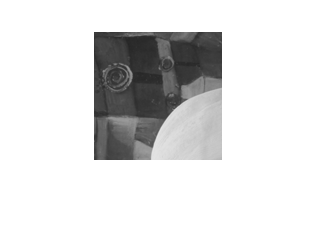

imshow(right);

tic
D_L2 = disparity_ssd(left,right,3);
toc

Elapsed time is 23.918597 seconds.


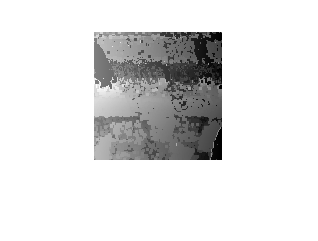

imshow(D_L2,[]);